## United States Carbon Emissions Arima Time Series Model

Author: Caitlyn Wei

Overview: Full end-to-end ML implementation of a short term time series model. Global Carbon Project 2023 Global Emissions dataset.

## Read Dataset

- total.csv : Global Carbon Project carbon emissions dataset

- population.csv : Global Carbon Project populatoin dataset

total = readtable("total.csv")

total = 60828×12 table
        Country        ISO3166_1Alpha_3    UNM49    Year    Total    Coal    Oil    Gas    Cement    Flaring    Other    PerCapita
    _______________    ________________    _____    ____    _____    ____    ___    ___    ______    _______    _____    _________

    {'Afghanistan'}        {'AFG'}           4      1750     NaN     NaN     NaN    NaN      0         NaN       NaN        NaN   
    {'Afghanistan'}        {'AFG'}           4      1751     NaN     NaN     NaN    NaN      0         NaN       NaN        NaN   
    {'Afghanistan'}        {'AFG'}          

population = readtable('population.csv'); 

usa = total(string(total.ISO3166_1Alpha_3) == 'USA', :);

usa_p = population(string(population.ISO3) == 'USA', :);

usa

usa = 274×12 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total    Coal    Oil    Gas    Cement    Flaring    Other    PerCapita
    _______    ________________    _____    ____    _____    ____    ___    ___    ______    _______    _____    _________

    {'USA'}        {'USA'}          840     1750     NaN     NaN     NaN    NaN     NaN        NaN       NaN        NaN   
    {'USA'}        {'USA'}          840     1751     NaN     NaN     NaN    NaN     NaN        NaN       NaN        NaN   
    {'USA'}        {'USA'}          840     1752     NaN     NaN     NaN    NaN 

usa_p

usa_p = 204×5 table
    CountryName     ISO3      UNcode    Year    Population
    ___________    _______    ______    ____    __________

      {'USA'}      {'USA'}     840      1820    9.9805e+06
      {'USA'}      {'USA'}     840      1821    1.0299e+07
      {'USA'}      {'USA'}     840      1822    1.0626e+07
      {'USA'}      {'USA'}     840      1823    1.0951e+07
      {'USA'}      {'USA'}     840      1824    1.1277e+07
      {'USA'}      {'USA'}     840      1825    1.1602e+07
      {'USA'}      {'USA'}     840      1826    1.1928e+07
      {'USA'}      {'USA'}     840      1827    1.2251e+07
      {'USA'}      {'USA'}     840      1828    1.2581e+07
      {'USA'}      {'USA'}     840      1829    1.2906e+07
      {'USA'}      {'USA'}     840      1830     1.324e+07
      {'USA'}      {'USA'}     840      18

## Clean and Prepare Data

### Remove NaN values from dataset

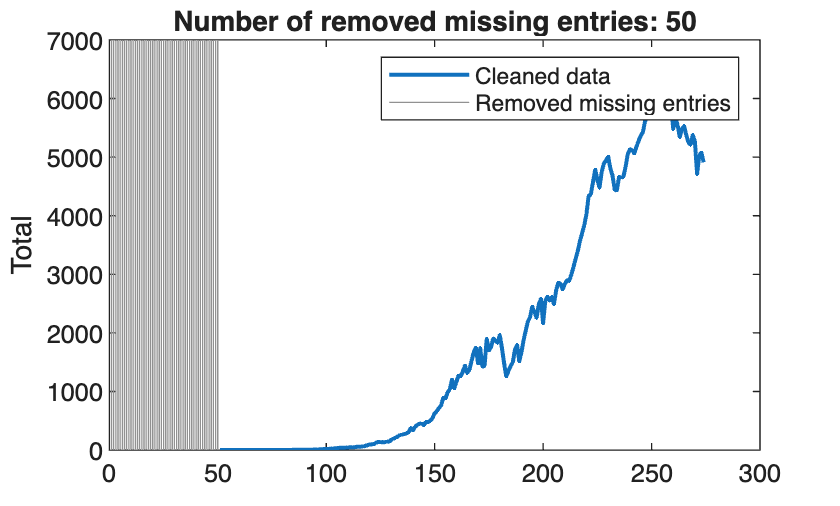

% Remove missing data
[usa,missingIndices] = rmmissing(usa,DataVariables="Total");

% Display results
figure

% Plot cleaned data
plot(find(~missingIndices),usa.Total,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,DisplayName="Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("Total")

clear x y
usa

usa = 224×12 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________

    {'USA'}        {'USA'}          840     1800    0.25282    0.25282     0      0       0         NaN       NaN     0.042136 
    {'USA'}        {'USA'}          840     1801    0.26747    0.26747     0      0       0         NaN       NaN     0.043749 
    {'USA'}        {'USA'}          840     1802    0.28946 

## Split data into training and test sets

- usaTrain : training set 1800-2018

- usaTest : test set 2019-2023

Major changes in carbon emissions after Kyoto Agreement (1997) and Paris Agreement (2015)

- Predicting for 5 years (test set)

- Split by index

% Training and test indices
n = height(usa);
train_size = floor(0.98 * n);

trainIdx = false(n, 1);
testIdx = false(n, 1);

trainIdx(1:train_size) = true;
testIdx(train_size+1:end) = true;

% Create training and test sets
usaTrain = usa(trainIdx, :);
usaTest = usa(testIdx, :);


disp(['Training set size: ', num2str(sum(trainIdx))]);

Training set size: 219


disp(['Test set size: ', num2str(sum(testIdx))]);

Test set size: 5


## Make data stationary

Stationary data is crucial for time-series models

Reduce variance by **transforming data, removing trends, and performing data decomposition**

### Visualize current dataset (USA)

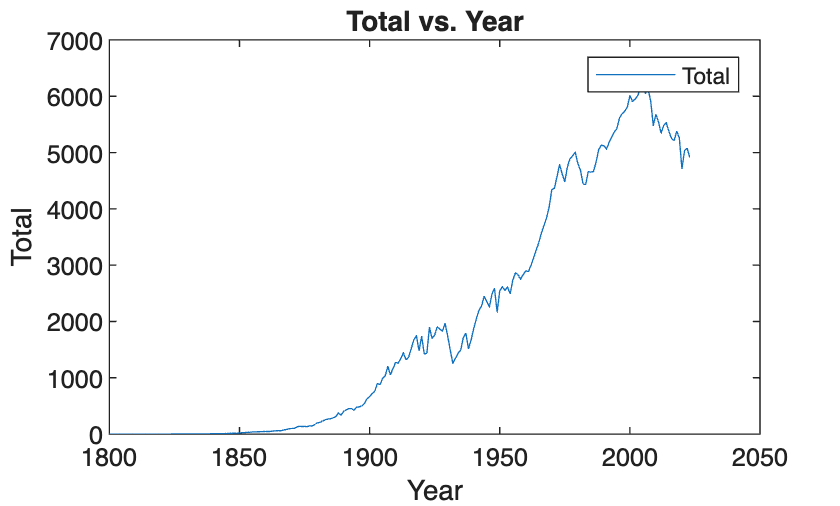

% Create plot of usa.Year and usa.Total
usaTotalYear = plot(usa,"Year","Total","DisplayName","Total");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("Total")
title("Total vs. Year")
legend

From this plot, we see that the data follows a generally exponential trend, thus we take the log to make the data more stationary.

### Transform Data

Take log of Total

usaTrain.log = log(usaTrain.Total);

% Visualize Transformation

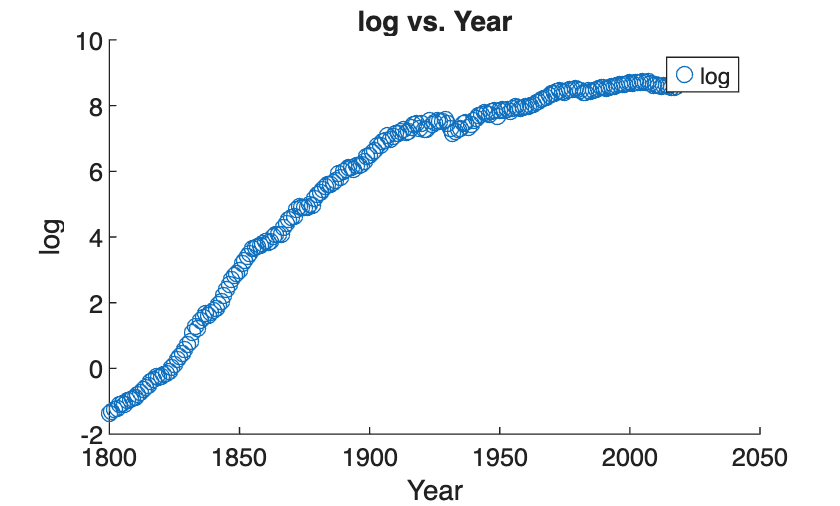

% Create scatter of usaTrain.Year and usaTrain.log
usaTrainTotalLog = scatter(usaTrain,"Year","log","DisplayName","log");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("log")
title("log vs. Year")
legend

### Remove Trends / Decompose Data

Remove quadratic, cubic, or higher order trends so that model can have flexibility

- Initial attempts with removing linear trend yielded modes that could not accurately fit to dataset

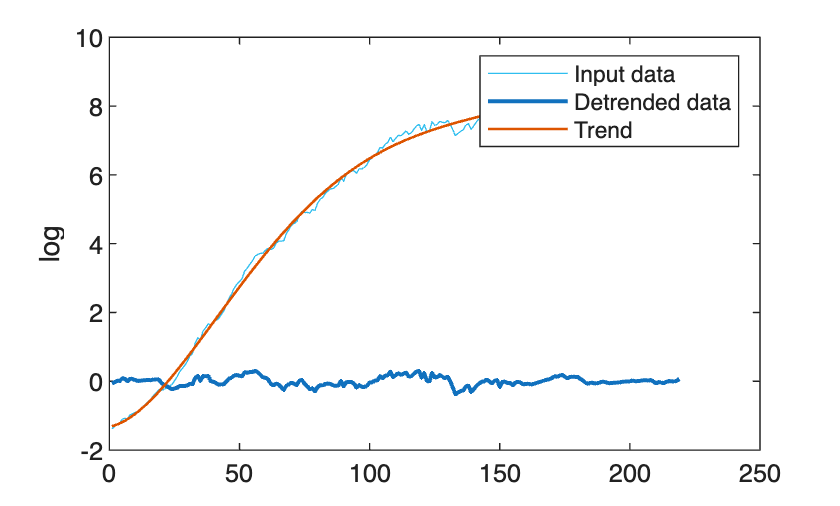

% Remove trend from input data
quinticTrendLog = detrend(usaTrain(:,"log"),5);

% Display results
figure
plot(usaTrain.log,SeriesIndex=6,DisplayName="Input data")
hold on
plot(quinticTrendLog.log,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(usaTrain.log-quinticTrendLog.log,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("log")

% Save Detrended Data --> dark blue line
usaTrain.quinticDetrendedLog = quinticTrendLog.log

usaTrain = 219×14 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita      log       quinticDetrendedLog
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    ________    ___________________

    {'USA'}        {'USA'}          840     1800    0.25282    0.25282     0      0       0         NaN       NaN     0.042136      -1.3751         -0.067994     
    {'USA'

% Save Trend --> orange line
usaTrain.quinticTrendLog = usaTrain.log-quinticTrendLog.log

usaTrain = 219×15 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita      log       quinticDetrendedLog    quinticTrendLog
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    ________    ___________________    _______________

    {'USA'}        {'USA'}          840     1800    0.25282    0.25282     0      0       0         N

## Model Individual Components

R^2: 0.72463

R^2: 0.99772

QuinticLogMdl = createQuinticFit(usaTrain.quinticTrendLog)

QuinticLogMdl =      Linear model Poly5:
     QuinticLogMdl(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =  -2.402e-10  (-2.402e-10, -2.402e-10)
       p2 =   1.459e-07  (1.459e-07, 1.459e-07)
       p3 =  -3.148e-05  (-3.148e-05, -3.148e-05)
       p4 =    0.002553  (0.002553, 0.002553)
       p5 =     0.01566  (0.01566, 0.01566)
       p6 =      -1.325  (-1.325, -1.325)

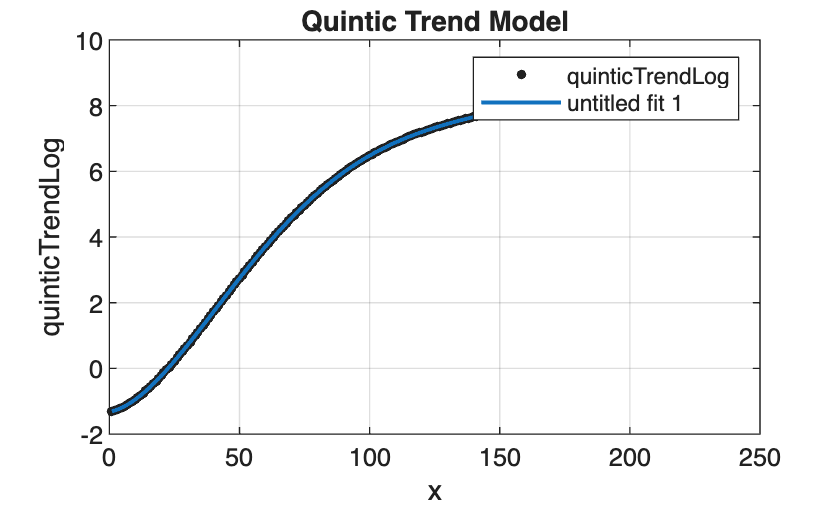

title("Quintic Trend Model")

### ACF and PACF of Remainder component (cubic detrended)

Utilize ACF and PACF plots to guide model selection

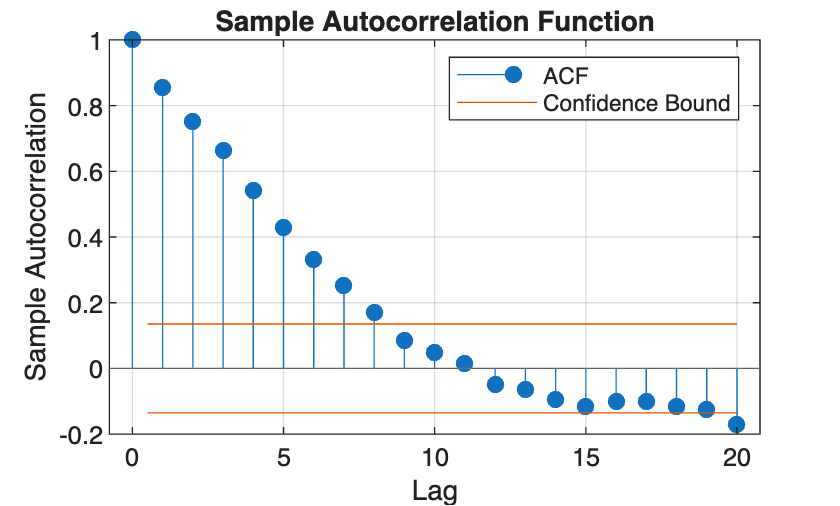

autocorr(usaTrain.quinticDetrendedLog, NumLags=20)

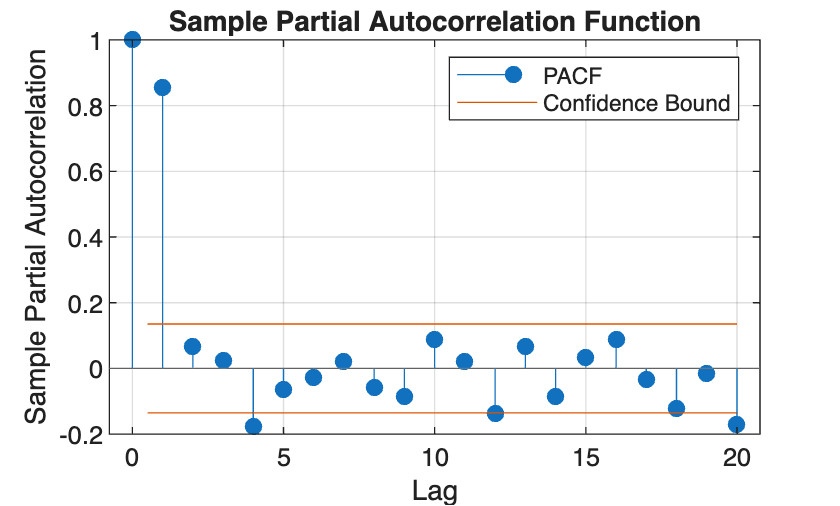

parcorr(usaTrain.quinticDetrendedLog, NumLags=20)

ACF plot does not show seasonality, suggesting use of ARIMA Model (1,0,0)

## Model Selection and Forecasting

frcst = table;
height(frcst)

ans = 0

frcst.Year = usaTest.Year;
height(frcst)

ans = 5

prevIdx = height(usaTrain)

prevIdx = 219

frcst.Idx = (prevIdx+1:prevIdx+height(frcst))'

frcst = 5×2 table
    Year    Idx
    ____    ___

    2019    220
    2020    221
    2021    222
    2022    223
    2023    224


frcstHorizon = height(frcst)

frcstHorizon = 5

frcst.Idx

ans =    220
   221
   222
   223
   224


### Set up model components

frcst.QuinticLogFrcst = feval(QuinticLogMdl, frcst.Idx);

### Gridsearch for ARIMA Parameters p and q

p_range = 0:5;
q_range = 0:5;

% store model results
results = [];

% Grid search on residuals
for p = p_range
    for q = q_range
        try
            % Fit ARIMA model with d=0
            model = arima(p, 0, q);
            fit = estimate(model, usaTrain.quinticDetrendedLog, 'Display', 'off');
            
            % Get log-likelihood
            [~, ~, logL] = infer(fit, usaTrain.quinticDetrendedLog);
            
            numParams = p + q;
            if fit.Constant ~= 0 
                numParams = numParams + 1;
            end
            
            n = length(usaTrain.quinticDetrendedLog);
            
            aic = -2*logL + 2*numParams;
            bic = -2*logL + numParams*log(n);
            
            % Store results: [p, q, AIC, BIC, LogLikelihood]
            results = [results; p, q, aic, bic, logL];
            
        catch ME
            fprintf('Failed to fit ARIMA(%d,0,%d): %s\n', p, q, ME.message);
            continue;
        end
    end
end

% Convert to table for easier viewing
resultsTable = array2table(results, ...
    'VariableNames', {'p', 'q', 'AIC', 'BIC', 'LogLikelihood'});

% Sort by AIC (lower is better)
resultsTable = sortrows(resultsTable, 'AIC');

% Display top 10 models
disp('Top 10 models by AIC:');

Top 10 models by AIC:


disp(resultsTable(1:min(10, height(resultsTable)), :));

    p    q      AIC        BIC      LogLikelihood
    _    _    _______    _______    _____________

    4    3    -572.62    -545.51       294.31    
    2    4    -572.54    -548.82       293.27    
    5    1    -571.91    -548.18       292.95    
    5    4    -571.51    -537.62       295.76    
    2    5    -570.59    -543.48        293.3    
    3    4    -570.58    -543.47       293.29    
    3    5    -569.15    -538.65       293.58    
    4    5    -568.61    -534.72       294.31    
    1    3    -563.65     -546.7       286.82    
    4    0    -563.53    -546.58       286.76    



### Find best models (AIC, BIC)

[~, idx_aic] = min(resultsTable.AIC);
[~, idx_bic] = min(resultsTable.BIC);

fprintf('\n=== BEST MODELS ===\n');


=== BEST MODELS ===


fprintf('Best by AIC: ARIMA(%d,0,%d) - AIC = %.4f\n', ...
    resultsTable.p(idx_aic), resultsTable.q(idx_aic), resultsTable.AIC(idx_aic));

Best by AIC: ARIMA(4,0,3) - AIC = -572.6188


fprintf('Best by BIC: ARIMA(%d,0,%d) - BIC = %.4f\n', ...
    resultsTable.p(idx_bic), resultsTable.q(idx_bic), resultsTable.BIC(idx_bic));

Best by BIC: ARIMA(1,0,0) - BIC = -554.7375



% Fit the best model (by BIC)
best_p = resultsTable.p(idx_bic);
best_q = resultsTable.q(idx_bic);

fprintf('\nFitting best model: ARIMA(%d,0,%d)...\n', best_p, best_q);


Fitting best model: ARIMA(1,0,0)...


bestModel = arima(best_p, 0, best_q);
bestARIMAfit = estimate(bestModel, usaTrain.quinticDetrendedLog, 'Display', 'off');

% Display fitted model
disp(bestARIMAfit);

  arima with properties:

     Description: "ARIMA(1,0,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 0
        Constant: 0.00042541
              AR: {0.857327} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.00442652


## Model Forecast Predictions for next 5 years

frcst.ARIMABest = forecast(bestARIMAfit, frcstHorizon, usaTrain.quinticDetrendedLog);

% Untransform
frcst.Co2Forecast = exp(frcst.ARIMABest+frcst.QuinticLogFrcst); 


### RMSE: 381.9775 Mt

% Calculate RMSE (w/o indexing/removing 2019 2020)
E = rmse(frcst.Co2Forecast, usaTest.Total);

% Display the result
disp(['The RMSE is: ', num2str(E)]);

The RMSE is: 381.9775



avg_emission = mean(usaTest.Total)

avg_emission = 4.9998e+03

ref = E/avg_emission * 100

ref = 7.6398

### RMSE Per Capita: 1.128e-06 Mt

usa_norm = usa_p(end-4:end, "Population")

usa_norm = 5×1 table
    Population
    __________

    3.3432e+08
    3.3594e+08
      3.37e+08
    3.3829e+08
       3.4e+08


frcst.Co2PerCapita = frcst.Co2Forecast ./ usa_norm.Population;
usaTest.TotalPerCapita = usaTest.Total ./ usa_norm.Population;

Epc = rmse(frcst.Co2PerCapita, usaTest.TotalPerCapita);

% Display the result
disp(['The RMSE per capita is: ', num2str(Epc)]);

The RMSE per capita is: 1.128e-06



avgpc_emission = mean(usaTest.TotalPerCapita)

avgpc_emission = 1.4833e-05

ref_pc = Epc/avgpc_emission *100

ref_pc = 7.6045

## Plot Results

### Plot forecast against test data

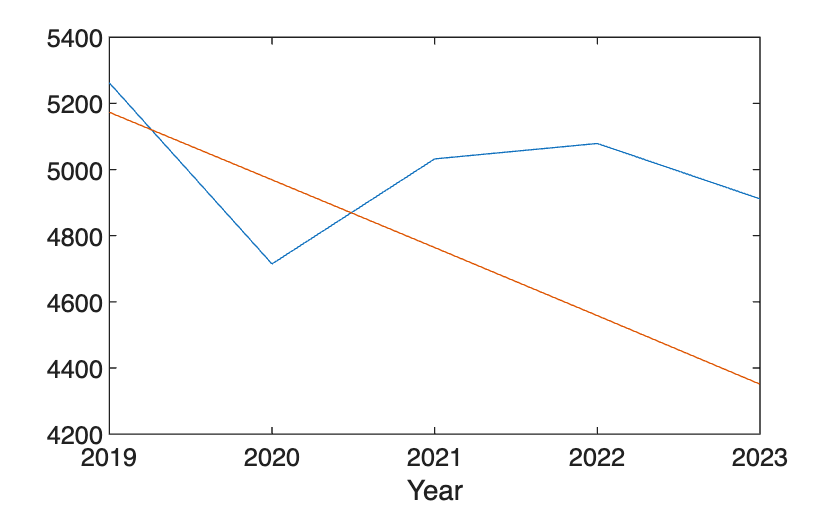

figure
% plot(usa, "Year", "Total")
% hold on
plot(usaTest, "Year", "Total")
hold on
plot(frcst,"Year","Co2Forecast")
hold off

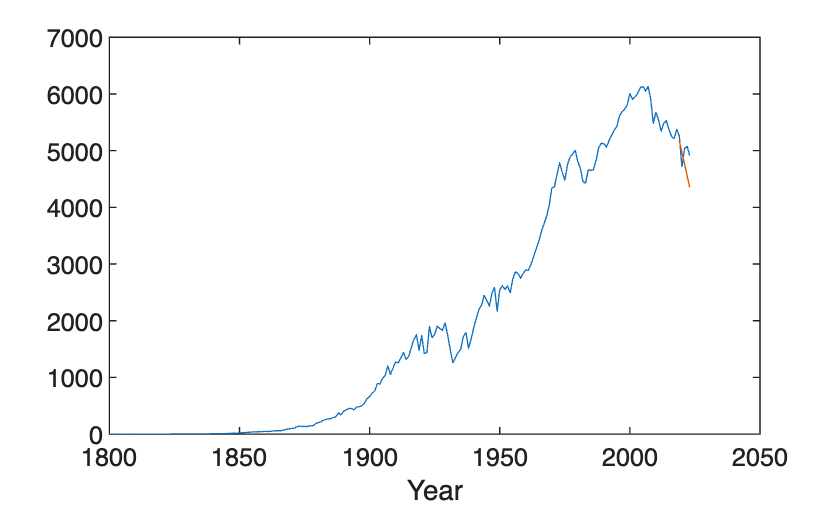

figure
plot(usa, "Year", "Total")
hold on
plot(frcst,"Year","Co2Forecast")
hold off

### Per Capita Plots

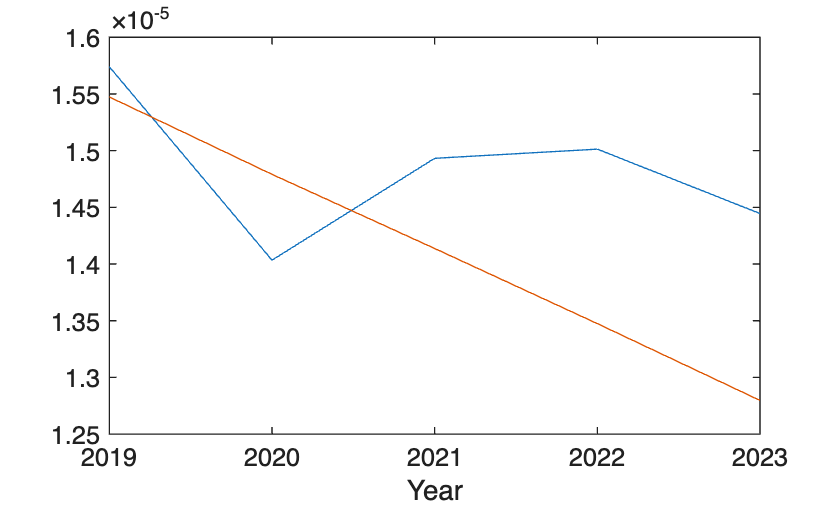

figure
plot(usaTest, "Year", "TotalPerCapita")
hold on
plot(frcst,"Year","Co2PerCapita")
hold off

usa_pc = table;
usa_pc.Total = usa.Total(21:end) ./ usa_p.Population;
usa_pc.Year = usa.Year(21:end)

usa_pc = 204×2 table
      Total       Year
    __________    ____

    7.9297e-08    1820
    8.0403e-08    1821
     8.138e-08    1822
    8.2306e-08    1823
    9.0002e-08    1824
    9.7897e-08    1825
    1.1028e-07    1826
    1.1814e-07    1827
    1.2669e-07    1828
    1.3911e-07    1829
    1.5774e-07    1830
    1.6578e-07    1831
    2.1472e-07    1832
     2.434e-07    1833
    2.2675e-07    1834
    2.8148e-07    1835


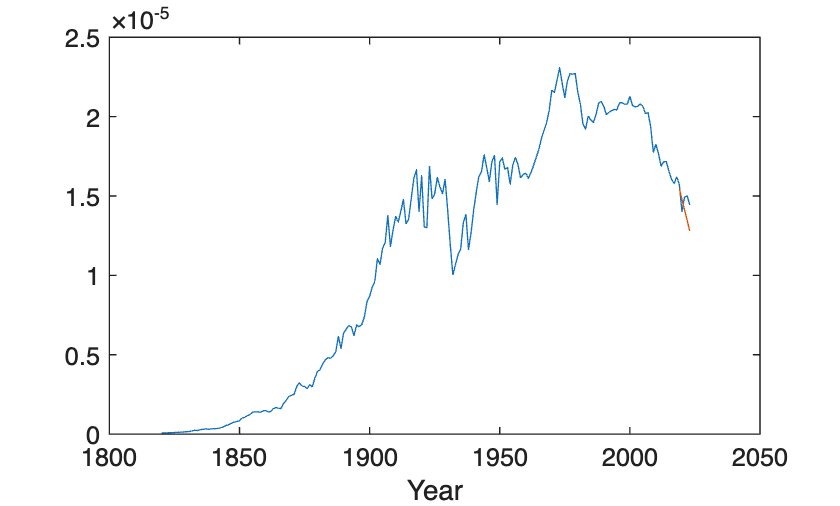

figure
plot(usa_pc, "Year", "Total")
hold on
plot(frcst,"Year","Co2PerCapita")
hold off